# Assignment 1

## Data Processing


% 0. Clear environment and remove all plots
clc % clears the command window
close all %removes all figures
clear % clears the workspace

% 1. Load the data
% 1.1 Loading the excel file into matlab
fileName =  "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx";
isfile(fileName)

ans = logical
   1


excelSheetNames = sheetnames(fileName);
% 1.2 Preallocate cell array before looping
data{numel(excelSheetNames)} = [];
% 1.3 Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
    data{sheet} = readtimetable(fileName, 'Sheet', excelSheetNames{sheet}, 'VariableNamingRule', 'preserve');
end

% 2. Filter and Clean Data: Keep Only Relevant Tickers and Columns
% 2.1 Define a list of all the assets we want to include in the universe
%      - Includes RATESTEFI, ALBI, key J-bonds, variable J5x tickers, and major JSE indices
variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'RATEJ2Y4', 'ALBI', 'J203', 'J500', 'J330', 'J331', variableTickers{:}};
% 2.2 Loop over each sheet in the dataset
for i = 1:numel(data)
    % 2.2.1 Keep only TRI (Total Return Index) columns for sheets 3 and 4
    if i == 3
        allVarTable = data{i}; 
        TRITable = allVarTable(:, (3:3:27));   % select every 3rd column (TRI)
        TRITable = TRITable(4:end,:);          % remove the first 3 rows (NaNs)
        % Convert all columns to numeric if they are cells/strings 
        % (i.e. J500 needs converting)
        for col = 1:width(TRITable)
            colName = TRITable.Properties.VariableNames{col};
            % Check if the column is cell or string
            if iscell(TRITable.(colName)) || isstring(TRITable.(colName))
                TRITable.(colName) = str2double(TRITable.(colName));  % convert to numeric
            end
        end
        data{i} = TRITable;
    elseif i == 4
        allVarTable = data{i};
        allVarTable = removevars(allVarTable, ["SOURCE68779","Var2"]); % remove unwanted columns
        TRITable = allVarTable(:, (4:4:19));   % select every 4th column (TRI)
        TRITable = TRITable(4:end,:);           % remove the first 3 rows (NaNs)
        data{i} = TRITable;
    else
        % 2.2.2 For other sheets, just skip the first 3 rows
        data{i} = data{i}(4:end, :);  
    end
    % 2.3 Match column names to entities (whitelist)
    opts = data{i}.Properties;                  % get table properties
    variableMatch = zeros(size(opts.VariableNames));  % preallocate array for matching
    % 2.3.1 Perform string comparison for column matching
    if i == 2 
        % Sheet 2: compare first 8 characters to avoid unwanted matches
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 8)) = k;
        end
    else
        % Other sheets: compare first 4 characters
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 4)) = k;
        end
    end
    % 2.3.2 Identify and remove columns not in the whitelist
    idx = find(variableMatch == 0);                    % find unwanted tickers
    tickersToBeRemoved = opts.VariableNames(idx);      % get their names
    data{i} = removevars(data{i}, tickersToBeRemoved); % remove them from the table
    % 2.4 Clean up remaining column names
    %      - Remove any text after ':' to simplify variable names
    hasColon = contains(data{i}.Properties.VariableNames, ':');     
    data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon), ':');
end

% 3. Clean and convert into a single timetable
allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','RATEJ2Y4','J203'}, {'STEFI','JIBAR','ALSI'});

% 4. Down-sample (by decimation)
% 4.1 Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable); % Home -> Add-ons -> Financial Toolbox

% 5. Visualising and Handling Missing Data
% 5.1 Initial Missing Data Visualisation
figure;
subplot(1,6,1);
spy(isnan(table2array(allDataTable)));
ylabel("Assets Index")
xlabel("Date Index")
title("Missing Data")
% 5.2  Fill Missing Data with Zero-Order Hold (Last Observation Carried Forward)
allDataTableFilled = fillmissing(allDataTable,'previous');
subplot(1,6,2);
spy(isnan(table2array(allDataTableFilled)));
% 5.3 Remove Rows Using the Asset With The Least NaN's (best proxy asset)
[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy = allDataTable.Properties.VariableNames{idx}; % Find the column with the FEWEST missing values
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy); % Remove rows where the proxy has NaNs
subplot(1,6,3);
spy(isnan(table2array(allDataTable)));
% 5.4 Drop a Specific Variable (J500 - discontinued)
idxJ500=contains(allDataTable.Properties.VariableNames,'J500');
idx = 1:width(allDataTable);
allDataTable = allDataTable(:,idx(~idxJ500))

allDataTable = 261×14 timetable
       Time        ALBI    JIBAR    STEFI     J510      J520      J530      J540      J550      J560      J580      J590     J331    J330     ALSI 
    ___________    ____    _____    _____    ______    ______    ______    ______    ______    ______    ______    ______    ____    ____    ______

    30-Jun-1995    NaN      NaN      NaN     357.54    493.64    232.92    512.36    992.26    526.97    476.25    695.15    NaN     NaN      36

subplot(1,6,4);
spy(isnan(table2array(allDataTable)));
% 5.5 Remove Rows Using the Asset With the Most NaNs
% Clean rows with missing data using the asset with the most gaps as a proxy.
[countNans,idx] = max(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable0 = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
% 5.6 Remove Leading Rows with Missing Data
% Detect rows at the start of the dataset that contain NaNs and trim them
idx = isnan(allDataTable{:,:});
allDataTable = allDataTable(max(find(idx,max(max(cumsum(idx)))))+1:end,:);
subplot(1,6,5);
spy(isnan(table2array(allDataTable)));
% 5.7 Remove Trailing Rows and Fill Remaining Missing Data
countNans = max(max(cumsum(isnan(allDataTable{:,:}))));
allDataTable = allDataTable(1:end-countNans+1,:);
allDataTableFilled = fillmissing(allDataTable,'previous')

allDataTableFilled = 146×14 timetable
       Time         ALBI     JIBAR    STEFI      J510      J520      J530      J540      J550      J560      J580      J590      J331      J330      ALSI 
    ___________    ______    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Nov-2004    205.71     7.45    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26

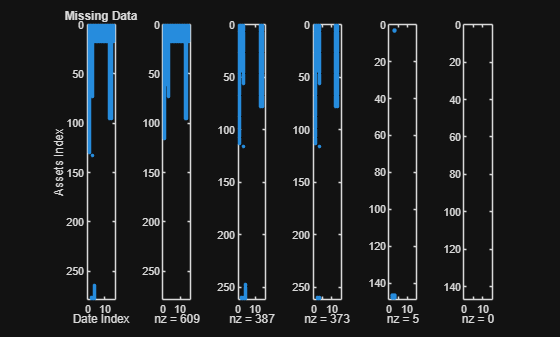

subplot(1,6,6);
spy(isnan(table2array(allDataTableFilled)));

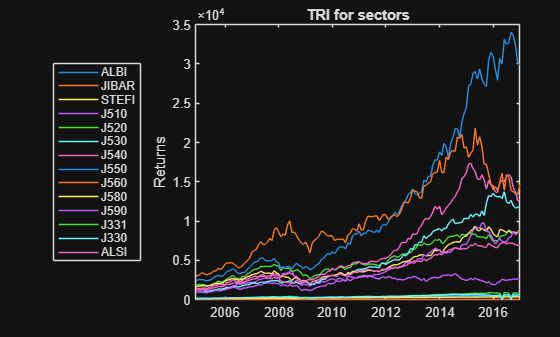


% 6. Visualise the data and the returns on a single plot
% 6.1 Compute simple returns (Rt = (Pt - Pt-1)/Pt-1)
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple');
% 6.2 Plot of the time series
figure;
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
title("TRI for sectors")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

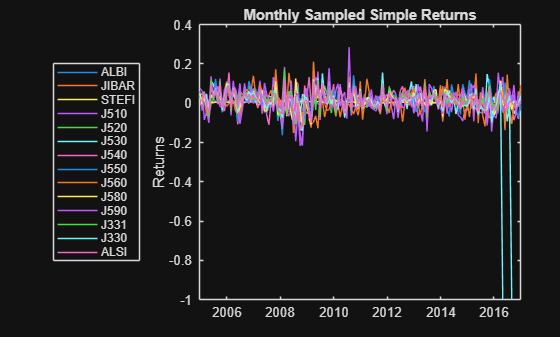

% 6.3 Plot of returns
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

% 6.4 Handle outlier (J330 and J331)
outlierIdx = allDataReturnsTable.("J330") < -0.5;
outlierRows = find(outlierIdx); 
disp(table( ...
    outlierRows, ...
    allDataReturnsTable.Time(outlierRows), ...
    allDataReturnsTable.("J330")(outlierRows), ...
    allDataReturnsTable.("J331")(outlierRows), ...
    'VariableNames', {'RowIndex', 'Date', 'J330_Return', 'J331_Return'})); % Display the outliers

    RowIndex       Date        J330_Return    J331_Return
    ________    ___________    ___________    ___________

      137       30-Apr-2016        -1             -1     
      141       31-Aug-2016        -1             -1     



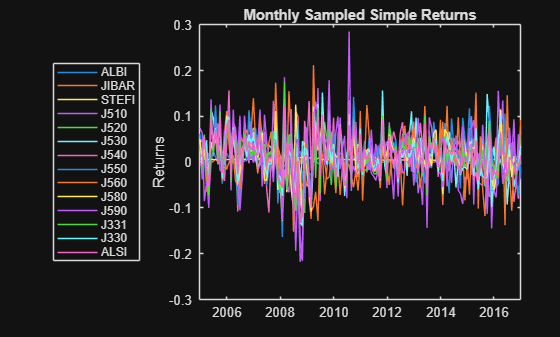

allDataReturnsTable.("J330")(outlierIdx) = NaN; % set the outliers to NaN
allDataReturnsTable.("J331")(outlierIdx) = NaN; % set the outliers to NaN
% 6.5 Plot of returns without the outliers
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")


% 7. Manage Missing Data
% 7.1 Check if there is still missing data or cells of zero
any(isnan(allDataReturnsTable{:,:}))

ans = 1×14 logical array
   0   0   1   0   0   0   0   0   0   0   0   1   1   0


nZeros = sum(allDataTable{:,:} == 0,'all');
disp(['Total zero values: ', num2str(nZeros)]);

Total zero values: 4


% 7.2 Compute the Arithmetic means correcting for missing data (NAN)
portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');
% 7.3 Fill those missing values with the previous results
allDataTable{:,:}(allDataTable{:,:} == 0) = NaN; % Replace zeros with NaN
allDataTable = fillmissing(allDataTable,'previous'); % Replace NaNs with the previous observation


## Experiment 1

### Data Set Up

% 1. Split into two sets of data
% 1.1 Number of observations
nObs = size(allDataTable,1);
% 1.2 Choose a split point (e.g. 70% training, 30% test)
splitPoint = floor(0.7 * nObs);
% 1.3 Also keep the dates if you need them
train = allDataTable(1:splitPoint,:);
test  = allDataTable(splitPoint+1:end,:);
disp(['Training rows: ', num2str(size(train,1))]);

Training rows: 102


disp(['Test rows: ', num2str(size(test,1))]);

Test rows: 44


### Training

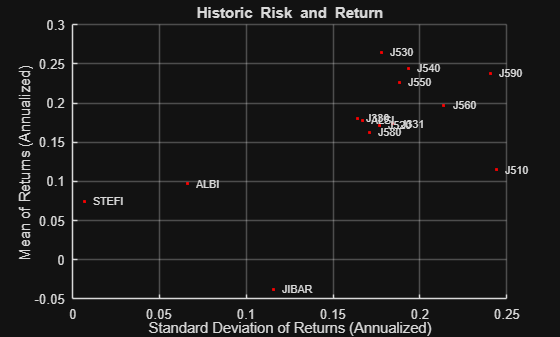

% 2.1 Portfolio Set Up
q = Portfolio('AssetList',train.Properties.VariableNames);
% 2.2 Simple Arithmetic Returns
trainReturnsTable = tick2ret(train,'Method','Simple'); % Change this if needed
q = estimateAssetMoments(q,trainReturnsTable{:,:});
% 2.3 Visualise the Risk-Return Relationship
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Fully invested portfolio with varying risk aversion

% 3. Fully invested portfolio with varying risk aversion 
% 3.1 Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);

% 3.2 Fully Invested
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;
PortWts = NaN(length(lambda),length(q.AssetMean));

% 3.3 Find the optimal portfolio weights
for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,[],[],q.AEquality,q.bEquality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

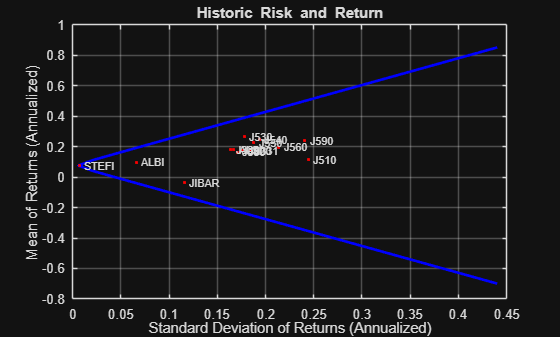

% 3.4 Compute Portfolio Risk and Return
ret0 = estimatePortReturn(q, PortWts');
rsk0 = estimatePortRisk(q,PortWts');
%ret = PortWts * q.AssetMean';
%rsk = sqrt(diag(PortWts * q.AssetCovar * PortWts'));

% 3.5 Plot the Curve
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk0, ret0}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow$Excluding Cash and Market Indices

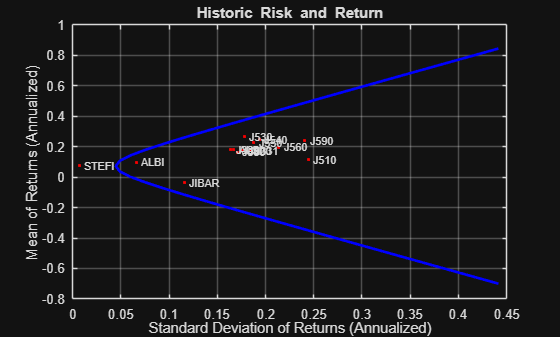

% 4. Exclude the Cash and Market Indices
% 4.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI'});
Returns = trainReturnsTable{:,tickers};
mu = mean(Returns); % Use Mean With Excluded Indices
Sigma = cov(Returns); % Use Covar With Excluded Indices

% 4.2 Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);

% 4.3 Fully Invested
Aeq = ones(1,length(mu));
beq = 1;
% initialise the weights
PortWts = NaN(length(lambda),length(mu));

% 4.4 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,[],[],[],optionsQP);
end

% 4.5 compute risk and return 
ret1 = PortWts * mu';
rsk1 = sqrt(diag(PortWts * Sigma * PortWts'));

%  4.6 Plot
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk1, ret1}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow \;$No short selling constraint (Method 1: Adjusting Risk Aversion)

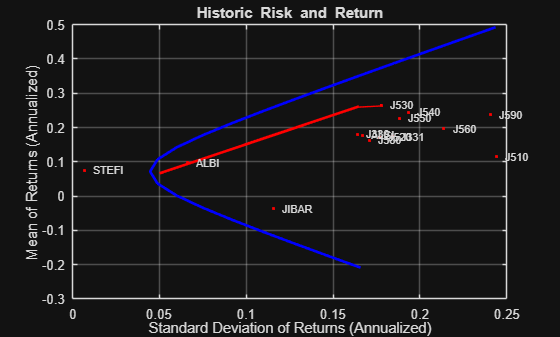

% 5. Exclude the Cash and Market Indices
% 5.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI'});
Returns = trainReturnsTable{:,tickers};
mu = mean(Returns); % Use Mean With Excluded Indices
Sigma = cov(Returns); % Use Covar With Excluded Indices

% 5.2 Create the range of risk aversion parameters
lambda = 12*linspace(0,1,25);

% 5.3 Fully Invested (equality constraint)
Aeq = ones(1,length(mu));
beq = 1;
% initialise the weights
PortWts = NaN(length(lambda),length(mu));

% 5.4 No Short-selling (inequality constraint)
A = -eye(length(mu));
b = zeros(length(mu),1);

% 5.5 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,A,b,Aeq,beq,[],[],[],optionsQP);
end

% 5.6 compute risk and return
ret2 = PortWts * mu';
rsk2 = sqrt(diag(PortWts * Sigma * PortWts'));

% 5.7 Plot
clf;
portfolioexamples_plot('Historic Risk and Return', ...
    {'line', rsk1(15:end-10), ret1(15:end-10)}, ...
	{'line', rsk2, ret2, '','r'}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\iff \;$No short selling constraint (Method 2: Adjusting Risk Aversion)

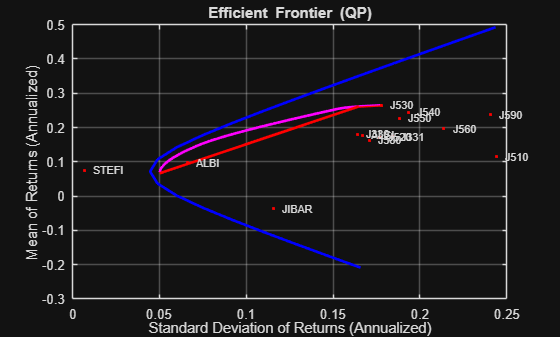

% 6. Exclude the Cash and Market Indices
% 6.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI'});
Returns = trainReturnsTable{:,tickers};
mu = mean(Returns); % Use Mean With Excluded Indices
Sigma = cov(Returns); % Use Covar With Excluded Indices

% 6.2 Create the range of risk aversion parameters
retTargetAll = min(mu):((max(mu)-min(mu))/90):max(mu);
retTarget = retTargetAll(retTargetAll > 0.0058);

% 6.3 Equality constraint (fully invested)
Aeq = ones(1,length(mu));
beq = 1;
% initialise the weights
PortWts = NaN(length(retTarget),length(mu));

% 6.4 No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);

% 6.5 Equality constraint (return target)
Aeq = [Aeq; mu];
beq = [beq; 0];

% 6.6 Find the optimal portfolio weights
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
for i = 1:length(retTarget)
    beq(2) = retTarget(i); % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,zeros(size(mu))',[],[],Aeq,beq,lb,ub,[],optionsQP);
end

% 6.7 compute risk and return
ret3 = PortWts * mu';
rsk3 = sqrt(diag(PortWts * Sigma * PortWts'));

%  6.8 Plot
clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
    {'line', rsk1(15:end-10), ret1(15:end-10)}, ...
	{'line', rsk3, ret3,'','m'}, ...
	{'line', rsk2, ret2,'','r'}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow \;$Maximum Sharpe Ratio Portfolio

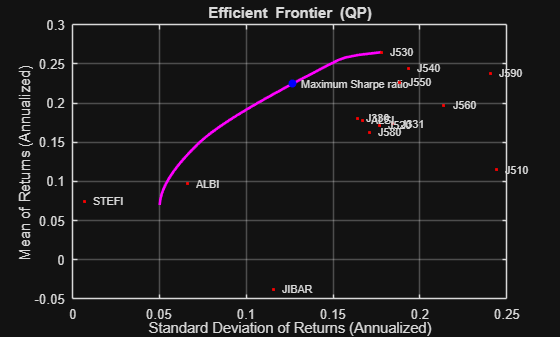

% 7 Exclude the Cash and Market Indices
% 7.1 Tickers we are excluding 
tickers = setdiff(train.Properties.VariableNames,{'STEFI','ALSI'});
Returns = trainReturnsTable{:,tickers};
mu = mean(Returns); % Use Mean With Excluded Indices
Sigma = cov(Returns); % Use Covar With Excluded Indices

% 7.2 Risk free rate
RFR = trainReturnsTable{:,{'STEFI'}};
% average risk free rate (when to use geometric average)
ERFR = mean(RFR); 

% 7.3 Equality constraint (fully invested)
Aeq = ones(1,length(mu));
beq = 1;
% initialise the weights for Equally weighted portfolio 
Wts0 = ones(size(mu))/length(mu);

% 7.4 No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);

% 7.5 objective function to maximise the SR
fn0 = @(x) (-(x*mu' - ERFR)/sqrt(x*Sigma*x'));

% 7.6 Use SQP to solve for the tangency portfolio
options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8,'Display','off');
Wts = fmincon(fn0,Wts0,[],[],Aeq,beq,lb,ub,[],options); % Maximum Sharpe Ratio Portfolio Weights

% 7.7 compute risk and return
retSR = Wts*mu';
rskSR = sqrt(Wts*Sigma*Wts');

% 7.8 Plot
clf; 
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk3, ret3,'','m'}, ...
    {'scatter',rskSR,retSR,{'Maximum Sharpe ratio'},'b'}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
hold on;

#### Market Security Line

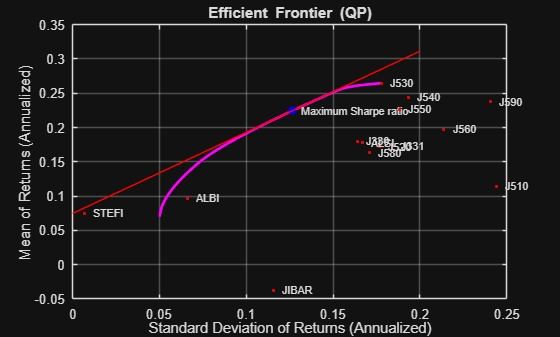

hold on
% 8.1 SML through the tangency portfolio
SML = @(x) (12*ERFR + sqrt(12)*(retSR-ERFR)/rskSR*x);
x = linspace(0,0.20,20);
% 8.2 Plot market line
plot(x,SML(x),'r')
% legend("Market Line")
hold off;

#### Visualise the Sharpe Ratio Values

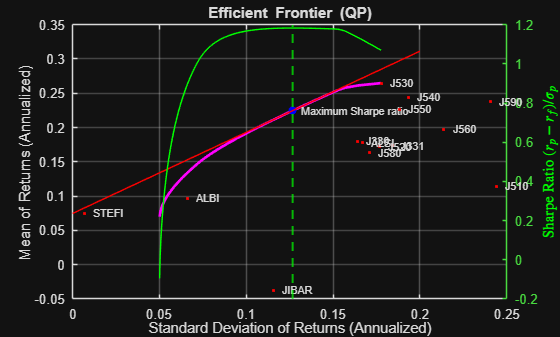

% 9.1 Plot the Sharpe Ratio against risk levels
yyaxis right
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex','Color','g')
% 9.2 plot the Sharpe Ratio against risk level
hold on
plot(sqrt(12)*rsk3,sqrt(12)*(ret3-ERFR)./rsk3,'g')
xline(rskSR*sqrt(12), '--g', 'LineWidth', 1.5, ...
    'Label', '', 'LabelVerticalAlignment','bottom', 'LabelOrientation','horizontal');
hold off

### Testing

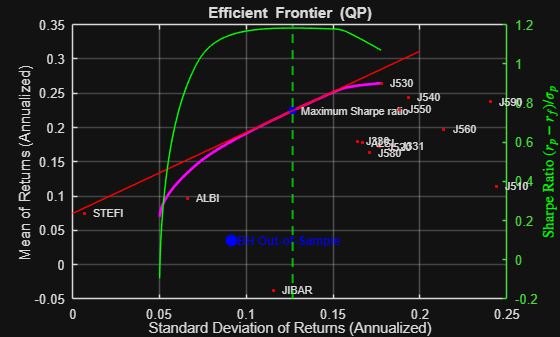

%% 10. Buy-and-Hold (BH) Strategy on Test Dataset
% 10.1 Extract test returns (excluding cash and market indices)
tickers = setdiff(test.Properties.VariableNames,{'STEFI','ALSI'});
testReturnsTable = tick2ret(test,'Method','Simple'); % Change this if needed
testReturns = testReturnsTable{:,tickers};

% 10.2 Compute Buy Hold Out of Sample Portfolio statistics
bhMean = mean(testReturns)* Wts';
bhVar  = Wts*cov(testReturns)*Wts';
bhStd  = sqrt(bhVar);
bhSharpe = sqrt(12)*(bhMean-ERFR)./bhStd;

% 10.3 Plot
hold on
scatter(sqrt(12) * bhStd, 12 * bhMean, 80, 'b', 'filled'); % blue dot
text(sqrt(12) * bhStd+0.003, 12 * bhMean, 'BH Out-of-Sample', ...
     'FontSize', 9, 'Color', 'b', 'FontWeight', 'bold');
hold off

### Tables for Results Comparison

% 11.1 In-sample statistics
inMean   = retSR;
inVar    = rskSR^2;
inSharpe = sqrt(12)*(retSR - ERFR) ./ rskSR;

% 11.2 Comparison table
ResultsComparison = table( ...
    [inMean; bhMean], ...
    [inVar;  bhVar], ...
    [inSharpe; bhSharpe], ...
    'VariableNames', {'Mean','Variance','SharpeRatio'}, ...
    'RowNames', {'In-Sample SR','Out-of-Sample BH'});

disp('Comparison of In- and Out-of-Sample Portfolio Statistics:');

Comparison of In- and Out-of-Sample Portfolio Statistics:


disp(ResultsComparison);

                          Mean       Variance     SharpeRatio
                        ________    __________    ___________

    In-Sample SR        0.018721     0.0013378       1.1829  
    Out-of-Sample BH    0.008042    0.00070065      0.23707  




% 11.3 Portfolio weights table
WeightTable = array2table(Wts, 'VariableNames', tickers);
disp('Buy-and-Hold Portfolio Weights:');

Buy-and-Hold Portfolio Weights:


disp(WeightTable);

     ALBI         J330          J331         J510          J520        J530       J540         J550         J560         J580         J590        JIBAR   
    _______    __________    __________    _________    __________    _______    _______    __________    ________    __________    ________    __________

    0.18705    2.2204e-16    2.2204e-16    1.492e-22    2.2204e-16    0.47848    0.23452    7.9877e-24    0.031738    2.2204e-16    0.068212    1.0233e-22

